clear all;
close all;
clc;

# Localgini Thresholding Method

This code is designed to execute the global thresholding algorithm.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Set up

The Gurobi solver is initialised, as well as COBRAToolbox

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...     0

     0

Check osense*c - A'*lam - w = 0 (stationarity):
     0
     0


 > [gurobi] Primal optimality condition in solveCobraLP satisfied.
 > [gurobi] Dual optimality condition in solveCobraLP satisfied.


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab')
changeCobraSolver('gurobi', 'all')


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

ans = logical
   1


## Load the data

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

currentFolder = pwd

currentFolder = 'C:\Users\PC\OneDrive\Documentos\Systems_Biology_master\Internship\Internship\Thresholding\StanDep'

cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data')
data = readtable("data_TPM.xlsx")

data = 26269×49 table
      Ensembl_GeneID        BJ_Y1       BJ_Y2       BJ_Y3      BJ_OLD_1    BJ_OLD_2    BJ_OLD_3    IMR90_Y1    IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3    WI_38_Y1    WI_38_Y2    WI_38_Y3    WI_38_O1    WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD26_1 

h_k_g = readtable('NM2ENSG.xlsx')

h_k_g = 3804×5 table
    initial_alias      converted_alias         name                                                   description                                                     namespace     
    _____________    ___________________    ___________    __________________________________________________________________________________________________    ___________________

    {'NM_003859'}    {'ENSG00000000419'}    {'DPM1'   }    {'dolichyl-phosphate mannosyltransferase subunit 1, catalytic [Source:HGNC Symbol;Acc:HGNC:3005]'}    {'REFSEQ_MRNA_ACC'}
    {'NM_020423'}    {'ENSG00000000457'}    {'SCYL3'  }    {'SCY1 like pseudokinase 3 [Source:HGNC Symbol;Acc:HGNC:19285]'                                  }    {'REFSEQ_MRNA_ACC'}
    {'NM_001498'}    {'ENSG00000001084'}    {'GCLC'   }    {'glutamate-cysteine liga

%model = load('Human-GEM_Cobra_v1.01.mat')
%model = model.model
% model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
% model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis, so it is recommended to remove these. 

WE DON'T DO THIS ANYMORE BECAUSE WE ARE LOSING A LOT OF INFORMATION

USE THE PRUNED MODEL TO CALCULATE THE METABOLIC GENES AND REACTIONS, AND THE NOT PRUNE FOR THE HK AND THE CORE GENES AND REACTIONS

% [fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
% model = fluxConsistModel; % load the new model with no blocked reactions
% save('model', 'model');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
% model_genes = model.genes;
cd(currentFolder)

## Preprocessing

Depending on the dataset, different steps will be required. The points we are interested in obtaining are the ENSEMBL_IDs of the genes, the sample names, and normalising the gene expression data.

To normalise, a log10 of the data is made, to which a 1 is added to avoid that values that are 0 give -inf values.

Finally, a table is created with the new normalised data, the column names are the sample names, and the first column is the ENSEML_IDs.

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
%logged_data = log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(data_to_log)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)


## Processing the gene expression dataset

Not all genes in the dataset are metabolism-related genes. This part of the code is responsible for obtaining the expression of the metabolic genes (metabolic_genes).

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% % Create a vector just with the ensembl ids of the genes from the model
% model_genes = model.genes
% % Find indexes of the genes that are present in the metabolic model. 
% index_names = ismember(data.Ensembl_GeneID, model_genes);
% % take the rows of the dataset that match the indexes obtained before, with all the data 
% data_met = data(index_names, :)
% 
% sampleNames = data_met.Properties.VariableNames(2:end);

## StanDep

Change the name of the column that contains the Ensembl_ID to gene, and normalize the data, 

%Ensuring that the first colum is names 'gene' 
data_met = metabolic_genes_P;
data_met.gene = data_met.Properties.RowNames;
columnNames = ['gene', data_met.Properties.VariableNames];
data_met = data_met(:, columnNames);
data_met.gene_1 = [];
data_met.Properties.RowNames = {};
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met;
datalog10{:,2:end} = datalog10{:, 2:end};%(datalog10{:,2:end}+1)

Define the limits of the bins:

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

Pre-processing of the data for Standep

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data.Properties.VariableNames(2:end)';

Pre-processing of the metabolic model

%2nd the model data structure
modelData = getModelData(rnaData,model_p);

Pre-processing of the enzyme data 

%3rd the enzyme data structure
spec = getSpecialistEnzymes(model_p);  
prom = getPromEnzymes(model_p);
enzymeData = comparePromiscuousSpecific(spec,prom,modelData);

Set the parameters for the clustering analysis

% We then set our parameters...
distMethod = 'euclidean'; % distance method  maybe think one more robust than euclidean.
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
k = 10;

Clustering analysis

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.9691


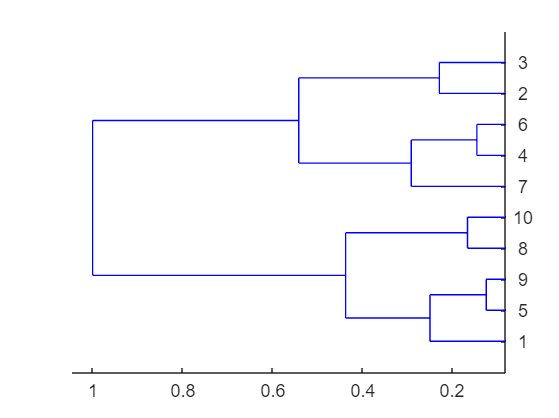

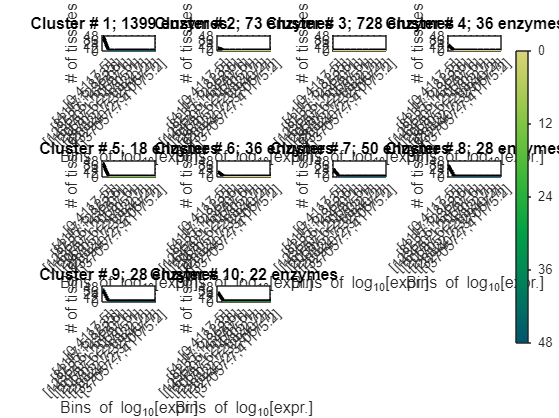

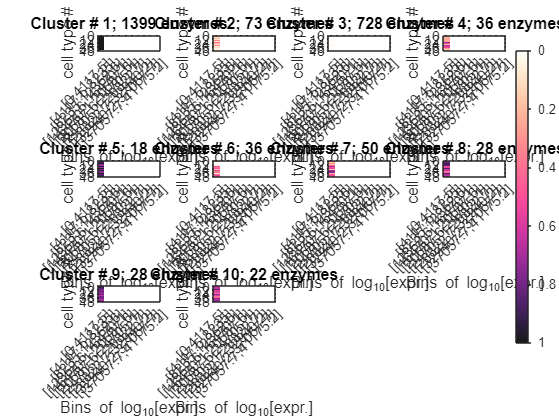

clustObj = struct with fields:
     Distribution: [2418×10 double]
          numObjs: [2418×1 double]
          objects: {2418×1 cell}
       objectMaps: {2418×1 cell}
                C: [10×10 double]
           cindex: [2418×1 double]
             Data: [2418×48 double]
    numObjInClust: [10×1 double]


close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy(enzymeData,[],edgeX,k,distMethod,linkageMethod)

Identify core reactions and calculate ubiquity score?

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model_p,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense

Top 25th percentile for the data = 1.5878
Mean of Data = 0.7385
Std. Dev. of Data = 0.2588
fraction selected = 1.0000
fraction selected = 0.0003
fraction selected = 0.0000
fraction selected = 0.0006
fraction selected = 0.0012
fraction selected = 0.0006
fraction selected = 0.0004
fraction selected = 0.0007
fraction selected = 0.0007
fraction selected = 0.0009


[ubiScore,uScore] = getUbiquityScore_2022(clustObj,edgeX,model_p); %ubiScore is the ubiquity score per rxns to use in mCadre!

Top 25th percentile for the data = 1.5878
Mean of Data = 0.7385
Std. Dev. of Data = 0.2588


# HOUSEKEEPING GENES 

ens_hkg = h_k_g.converted_alias;
index_names = ismember(ens_hkg, model_genes_p);
met_hkg = ens_hkg(index_names);

% Use this function to find the housekeeping reactions names
HKG_react = findRxnsFromGenes_Alicia(model_p, met_hkg); % Gives a structure, so the for loop to extract the names

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(HKG_react);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = HKG_react.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end

% Just want the name one time
housekeep_react_unique = unique(housekeep_react);


## Obtain core-reactions name

% Dimensiones de coreRxnMat
[numReactions, numSamp] = size(ubiScore);

% Inicializa la matriz de salida con celdas vacías
reactNames = cell(numReactions, numSamp);

% Recorre cada elemento de coreRxnMat
for i = 1:numReactions
    for j = 1:numSamp
        if ubiScore(i, j) >= 1
            % Si el elemento es 1, busca el nombre de la reacción correspondiente
            reactNames{i, j} = model_p.rxns{i};
        else
            % Opcional: Puedes dejar las celdas como vacías o poner algún marcador para indicar ausencia
            reactNames{i, j} = ''; % Asigna vacío o un marcador específico
        end
    end
end

% nombresReacciones ahora contiene los nombres de las reacciones para cada "1" en coreRxnMat

## Check the accuracy

% Inicializa la estructura para almacenar los resultados
comparisonResults = struct("numMatches", [], 'matchedElements', [], 'percentage', []);
totalReferenceElements = numel(housekeep_react_unique);

% Itera sobre cada columna de largeCellArray
for i = 1:size(reactNames, 2)  % Asumiendo que quieres comparar por columnas
    % Obtiene todos los elementos de la columna actual
    currentColumnElements = reactNames(:, i);
    % Aplana la cell array para asegurar una comparación adecuada
    currentColumnElements = vertcat(currentColumnElements{:});
    
    % Encuentra coincidencias entre los elementos de referencia y los elementos actuales
    matches = ismember(housekeep_react_unique, currentColumnElements);
    
    % Almacena los resultados en la estructura
    comparisonResults(i).numMatches = sum(matches);
    comparisonResults(i).matchedElements = housekeep_react_unique(matches);
    comparisonResults(i).percentage = (comparisonResults(i).numMatches / totalReferenceElements) * 100;
end

% Genera una tabla con los porcentajes de coincidencias
percentages = [comparisonResults.percentage]';
comparisonTable = table(percentages, 'VariableNames', {'HK_R_acc_SD'});

% Guarda la tabla en un archivo Excel
writetable(comparisonTable, "MatchComparisonResults.xlsx", 'WriteRowNames', false);

## test

% Suponiendo que uScore es una matriz con 48 columnas
nSamples = size(uScore, 2); % Número de muestras, que son 48 en este caso
results = {}; % Inicializar el cell array de resultados, ajustaremos su tamaño más tarde

for sampleIdx = 1:nSamples
    uScoreOI = uScore(:, sampleIdx);
    ixrow = find(uScoreOI == 1);
    
    % Enzimas que tienen un uScore de 1 para la muestra actual
    enzymesOI = clustObj.objects(ixrow);
    
    % Inicializar un cell array temporal para los genes
    genes = {};
    
    % Procesar los nombres de los enzimas para extraer los genes
    for i = 1:length(enzymesOI)
        if contains(enzymesOI{i}, ' & ')
            splitParts = strsplit(enzymesOI{i}, ' & ');
            for ii = 1:length(splitParts)
                genes{i, ii} = splitParts{ii};
            end
        else
            genes{i, 1} = enzymesOI{i};
        end
    end
    
    % Convertir a un vector lineal y eliminar elementos vacíos
    linearGenes = reshape(genes.', [], 1);
    linearGenes = linearGenes(~cellfun('isempty', linearGenes));
    
    % Obtener genes únicos
    uniqueGenes = unique(linearGenes);
    
    % Guardar los genes únicos en el cell array de resultados
    results(1:length(uniqueGenes), sampleIdx) = uniqueGenes;
end

% Ahora, 'results' es un cell array donde cada columna contiene los genes únicos para cada muestra


## l

% Inicializa la estructura para almacenar los resultados
comparisonResults = struct("numMatches", [], 'matchedElements', [], 'percentage', []);
totalReferenceElements = numel(met_hkg);

% Itera sobre cada columna de largeCellArray
for i = 1:size(results, 2)  % Asumiendo que quieres comparar por columnas
    % Obtiene todos los elementos de la columna actual
    currentColumnElements = results(:, i);
    % Aplana la cell array para asegurar una comparación adecuada
    currentColumnElements = vertcat(currentColumnElements{:});
    
    % Encuentra coincidencias entre los elementos de referencia y los elementos actuales
    matches = ismember(met_hkg, currentColumnElements);
    
    % Almacena los resultados en la estructura
    comparisonResults(i).numMatches = sum(matches);
    comparisonResults(i).matchedElements = met_hkg(matches);
    comparisonResults(i).percentage = (comparisonResults(i).numMatches / totalReferenceElements) * 100;
end

% Genera una tabla con los porcentajes de coincidencias
percentages = [comparisonResults.percentage]';
comparisonTable = table(percentages, 'VariableNames', {'HK_G_acc_SD'});

% Guarda la tabla en un archivo Excel
writetable(comparisonTable, "MatchComparisonResults_G.xlsx", 'WriteRowNames', false);